# Étude de la classe classJCA_Rigid

Ce Live Script reproduit le fonctionnement de la classe `"classJCA_Rigid.m"` à partir du code source d'origine.

 Ici on décortique la classe "classJCA_Rigid.m" avec validation, mais cette place permet de faire seule de son côté en l'appelant avec une configuration donnée (travail autonome et invisible directement). La classe modélise le comportement acoustique d'une matrice poreuse rigide. 

A savoir que cette classe utilise d'autres classes autonome pour avoir accès à un des dossiers / la création d'un environnement ou récupérer des valeurs d'indicateurs disponibles dans d'autres méthodes.

Ici "classJCA_Rigid.m" est parent de "classsubelement.m", on verra plus tard l'utilité.

 On y calcule :

 - les paramètres équivalents (densité, compressibilité),

 - la célérité, impédance et nombre d'onde équivalents,

 - la matrice de transfert acoustique d'une couche poreuse rigide.  

 Les références principales sont :

 [1] Dupont, T. et al. (2011). *Acoustic Properties of Air-Saturated Porous Materials Containing Dead-End Porosity*.

 [2] Panneton, R. (2007). *Comments on the limp frame equivalent fluid model for porous media*.

 [3] Atalla & Sgard. *Modeling of perforated plates and screens using rigid frame porous models*.

 [4] Atalla & Sgard. *Propagation of sound in porous media, second edition*.

 [5] Panneton (1996). *Modélisation numérique tridimensionnelle par éléments finis des milieux poroélastiques*.

## --- Création de l'environnement ---

On suppose que tu as bien accès à la classe : "create_environnement" Toutes les classes ont besoin des propriétés d'environnement pour tourner cette classe nécessite dans l'ordre : température/pression statique/humidité/Fmin/Fmax/points/SPL (dB)(option supp) Cette classe permet d'avoir les paramètre de l'air / de déterminer le pas fréquentiel...

env = create_environnement(23, 100800, 22, 1, 2000, 200,'SPL',145);

## --- Création d'un matériaux de référence (ex. Verdière 2013) ---

Création d'une instance de la classe JCA_Rigid avec les paramètres définis material = classJCA_Rigid( section, thickness, porosity, tortuosity, air_flow_resistivity, viscous_caractersitic_length, thermal_caracteristic_length, options);

s = 1; % section (arbitraire)
w = 1; %largeur (x)
d = 1; % profondeur (y)
phi = 0.958;
tor = 1.94;
sig = 11188;
vl = 70e-6;
tl = 209e-6;
t = 50e-3; %épaisseur du matériau (z)

Création d'une instance de la classe JCA_Rigid avec les paramètres définis.

création de la config dans notre système de classe (bien respecter l'ordre (lignes 180-211) config = classJCA_Rigid.create_config(s, t, phi, tor, sig, vl, tl, w, d)); une fois la configuration enregistrée, il ne reste plus qu'à crée l'objet qui permettra ensuite de faire le travail de façon autonome et d'obtenir les paramètres équivalents et les matrices de transfert, dans le but ensuite d'enregistrer les informations dans l'objet et pouvoir l'utiliser dans la suite du travail.

obj = classJCA_Rigid(config)

## --- Ce que réalise l'objet créé, à partir de la configuration instaurée ---

### paramètres équivalents (lignes 51-133)

la description des matériaux poreux à structures alvéolaires nécessite un modèle de fluide équivalent dans lequel les effets dissipatifs d'origine thermique et visqueuse sont intégrés à la formulation des paramètres acoustiques effectifs. Ces paramètres peuvent ensuite être exploités dans la formulation de la matrice de transfert de la couche homogène pour définir l'atténuation des ondes acoustiques dans le matériau.

Les éléments présentés dans cette partie sont tirés de l'ouvrage \emph{Propagation of Sound in Porous Media} \cite{allardAtalla2009}. 

 Le modèle JCA (\emph{Johnson–Champoux–Allard}) permet d'estimer la densité équivalente  $$\rho_{eq}$$ et la compressibilité équivalente $$K_{eq}$$ d'un matériau poreux à partir de cinq paramètres mesurables : la porosité $$\phi$$, la tortuosité $$\alpha_{\infty}$$, la résistivité au passage de l'air $$\sigma$$, ainsi que les longueurs caractéristiques visqueuse  $\Lambda$ et thermique $$\Lambda'$$. Ces informations sont alors reprises dans la configurations données de la classe.

#### --- Étape 1 : Densité effective ρ_eq (effets visqueux, Johnson) ---

Densité équivalente  


$$\rho_{eq}(\omega) = \rho_0 \, \alpha_{\infty} \left[ 1 + \frac{\sigma\phi}{j \omega \rho_0 \alpha_{\infty}} \, G_J(\omega) \right]$$
    
$$G_J(\omega) = \sqrt{1 + j \frac{\omega}{H}}$$
     
$$H = \frac{\sigma^2 \Lambda^2 \phi^2}{4 \alpha_{\infty}^2 \eta \rho_0}$$


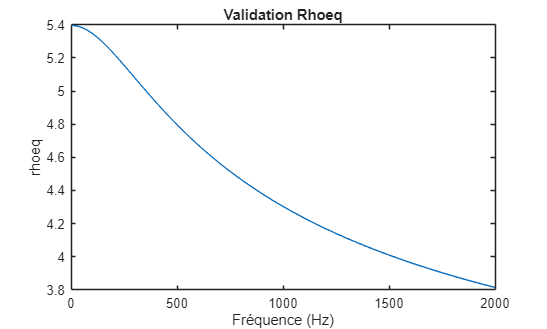

w = env.w;
f = env.f;
air = env.air;
param = air.parameters; 
P = air.StaticPressure; % Pression Statique
gam = param.gamma; % Indice Adiabatique de l'air
Pr = param.Pr; % Nombre de Prandt de l'air
eta = param.eta; % Viscosité de l'air
rho = param.rho; % Densité de l'air

H = phi^2 * vl^2 * sig.*conj(sig) ./ (4 * tor.*conj(tor) * rho .* eta); % fréquence caractéristique visqueuse
G = sqrt(1 + 1j .* w./H); 
rhoeq = rho .* tor .* (1 + (sig .* phi .* G) ./ (1j  .*  w .* rho .* tor));

figure;

plot(env.w/(2*pi), real(rhoeq))
% Mise en forme du graphique
xlabel('Fréquence (Hz)')
ylabel('rhoeq')
title('Validation Rhoeq')

#### --- Étape 2 : Module de compressibilité équivalent K_eq (effets thermiques, Champoux-Allard) ---


$$K_{eq}(\omega) = \frac{\gamma P_0}{\gamma - (\gamma-1)\sqrt{1 +\frac{H'}{2 j \omega} G'_J(\omega)}}$$
   
$$G'_J(\omega) = \sqrt{1 + j \frac{\omega}{H'}}$$
   
$$H' = \frac{16 \eta}{\rho_0 {\Lambda'}^2}$$


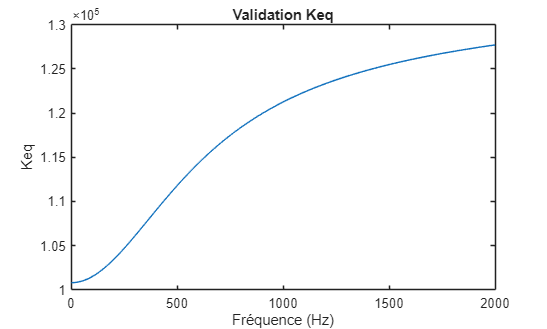

Hp = 16 * eta / (Pr * tl^2 .* rho); % fréquence caractéristique thermique 
Gp = sqrt(1 + 1j.* w ./ Hp);            
Keq = gam.* P./(gam - (gam-1)./(1 - 1j .* Hp .* Gp./(2 .* w)));

figure;
plot(env.w/(2*pi), real(Keq))
% Mise en forme du graphique
xlabel('Fréquence (Hz)')
ylabel('Keq')
title('Validation Keq')

#### --- Étape 3 : Grandeurs acoustiques équivalentes ---


$$Z_{{eq}}(\omega) = \sqrt{\rho_{eq}(\omega)\, K_{eq}(\omega)}$$
     
$$k_{eq}(\omega) = \sqrt{\frac{K_{eq}(\omega)}{\rho_{eq}(\omega)}}$$


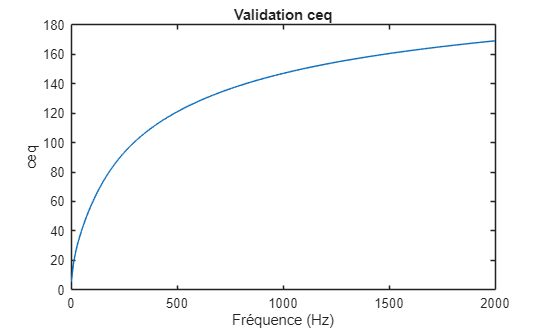

ceq = sqrt(Keq ./ rhoeq); % célérité équivalente
Zeq = sqrt(rhoeq .* Keq); % impédance caractéristique équivalente
keq = w ./ ceq; % nombre d'onde équivalent

figure;
plot(env.w/(2*pi), real(ceq))
% Mise en forme du graphique
xlabel('Fréquence (Hz)')
ylabel('ceq')
title('Validation ceq')

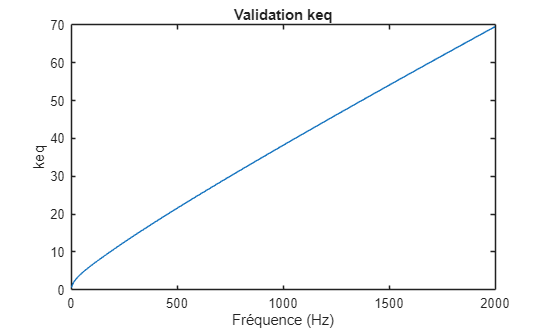


figure;
plot(env.w/(2*pi), real(keq))
% Mise en forme du graphique
xlabel('Fréquence (Hz)')
ylabel('keq')
title('Validation keq')

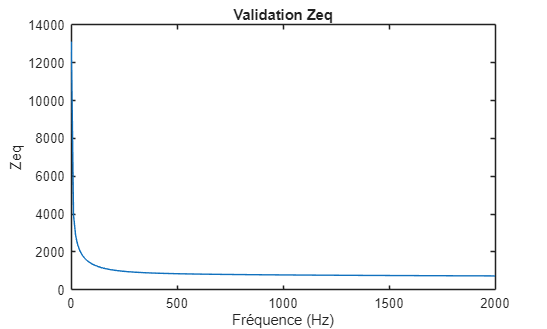


figure;
plot(env.w/(2*pi), abs(Zeq))
% Mise en forme du graphique
xlabel('Fréquence (Hz)')
ylabel('Zeq')
title('Validation Zeq')

A noter que dans la classe les paramètres sont d'abord appelés eff (effectif) avant d'être nommés eq (équivalent) et une normalisation est faite pour obtenir d'autres grandeurs (pas utiles pour cette classe ex : Kneq). Les variables normalisées ne sont pas nécessaires dans l'utilisation première de la classe.

Dans la classe, ep est donc variable muette qui contient alors tous les paramètres équivalents obtenus à l'aide de l'objet (donc de la config). On peut les observer en tapant "classJCA_Rigid.ep".

### Matrice de transfert du fluide équivalent

Si la couche est cylindrique (section constante, base de forme quelconque), alors le champ est unidimensionnel. La relation entre

**la pression et le débit acoustique à l’entrée (𝑝, 𝑢) et à la sortie (𝑝′, 𝑢′) de la couche peut prendre la forme matricielle suivante : **


$$T=\left\lbrack \begin{array}{cc}
\cos \left(\mathrm{kd}\right) & j\frac{Z}{S}\sin \left(\mathrm{kd}\right)\\
j\frac{S}{Z}\sin \left(\mathrm{kd}\right) & \cos \left(\mathrm{kd}\right)
\end{array}\right\rbrack$$


On remplace alors les paramètres "classiques" par les paramètres équivalents de la section précédente pour le modèle JCA.

Ici on calcule TM "à la main" mais dans la classe JCA_Rigid, TM est également une variable muette pouvant transmettre des informations de sortie lorsqu'elles sont demandées ou utiliser dans d'autres méthodes.

On appelle artificiellement ici les paramètres équivalent mais la méthode TM appelle elle en réalité  ep = obj.equivalent_parameters(env) pour avoir les paramètres acoustiques trouvées par l'autre méthode dans la même classe.

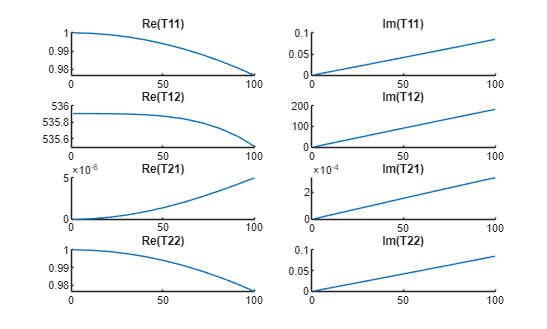

kt = keq * t; %on a renommé pour nous kd en kt
TM.T11 = cos(kt);
TM.T12 = 1j * Zeq / s .* sin(kt);
TM.T21 = 1j * s ./ Zeq .* sin(kt);
TM.T22 = cos(kt);


perso_plot_transfer_matrix(TM,env,'test',100)

## --- Conclusion ---

Cette classe est le fondement du travail envisagé dans le programme REAR, et va nous permettre de mieux comprendre le comportement de matériaux poreux à l'aide des fondements du modèle JCA.

En finalité, une classe n'est pas un script (elle ne peut pas tourner de façon autonome) et nécessite qu'on lui rentre une configuration initiale (à respecter scrupuleusement) / qu'on lui donne accès au dossier (launch_enviro.m) afin de pouvoir appeler d'autres éléments nécessaires. 

La classe permet alors de créer un objet avec une config, des paramètres équivalents et une matrice de transfert. On peut également valider le modèle avec une fonction "validate".

# Validation de la classe JCA

Pour valider la classe JCA, nous allons chercher à obtenir le coefficient d'absorption de notre matériaux (crée à partir de la config) afin de le comparer avec une courbe d'absorption observée dans la littérature (verdière).

## Données de littérature

data = csvread('Verdière2013_fig4_E.txt');
[x_data, y_data] = perso_interpole_et_lisse(data(:, 1), data(:, 2), 1000, 0.05);

## Détermination de alpha

Pour déterminer l'absorption de notre matériaux, nous avons la formule suivante :

$$$alpha = 1 - \left|  R_f\right|^2$$
$   avec   $$$R_f = \frac{Z_s - Z_0}{Z_s + Z_0}$$  $ 

Pour une condition terminale rigide ($Z_b = \infty$)  pour laquelle la vitesse acoustique en aval de la dernière couche s'annule, on obtient : 


$$$$Z_s \;=\; S_1\,\frac{t_{g,11}}{t_{g,21}}$$$$


L'idée est alors de trouver l'impédance de surface, pour obtenir R le coefficient de réflexion et enfin pouvoir obtenir alpha en fonction des fréquences.

Ces trois méthodes sont classés dans la classe "classsubelement.m" et nécessite d'être parent de notre classe JCA_rigid pour pouvoir communiquer entre elle, se transmettre l'environnement et l'objet créé.

Zs = s * TM.T11 ./ TM.T21; %impédance de surface
Z0 = param.rho * param.c0; %impédance de l'air
R = (Zs - Z0) ./ (Zs + Z0); %coefficient de réflexion
alpha = 1 - abs(R).^2; %coefficient de réflexion

Dans le contexte d'une classe, on tappe dans la commande directement "plot_alpha(obj,env,'name') qui est une fonction enregistrée dans "classsubelement", cette fonction nécessite les données de sortie de la fonction alpha à l'aide de l'objet créé, la méthode alpha nécessite elle les informations de la méthode "surface_impedance(obj,env)" et celle-ci nécessite les sorties de la méthode "transfert_matrix(obj,env)" qui est dans "classJCA_Rigid.m".

Toutes ces méthodes sont alors interdépendantes de la configuration initiale et donc ensuite de l'objet crée.

## Tracer alpha pour comparaison et validation de classJCA_Rigid

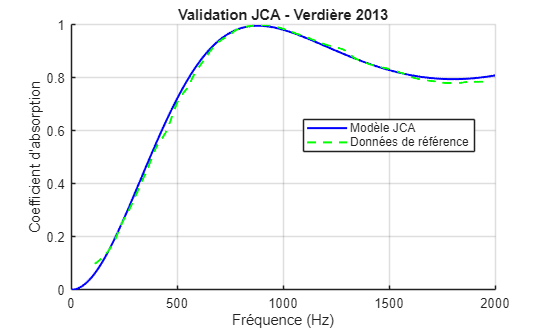

% --- Affichage du coefficient d'absorption ---

% Active le mode "hold" pour superposer les courbes
figure; % facultatif : crée une figure dans la sortie du Live Script
hold on
grid on

% Tracé du modèle JCA
plot(env.w / (2*pi), alpha, ...
    'Color', 'b', 'LineWidth', 1.5, ...
    'DisplayName', 'Modèle JCA');

% Tracé des données expérimentales / de référence
plot(x_data, y_data, ...
    'Color', 'g', 'LineWidth', 1.5, ...
    'LineStyle', '--', ...
    'DisplayName', 'Données de référence');

% Mise en forme du graphique
legend('Location', 'best')
xlabel('Fréquence (Hz)')
ylabel('Coefficient d''absorption')
ylim([0 1])
title('Validation JCA - Verdière 2013')

% Option Live Script : affiche le graphique sous la cellule
hold off